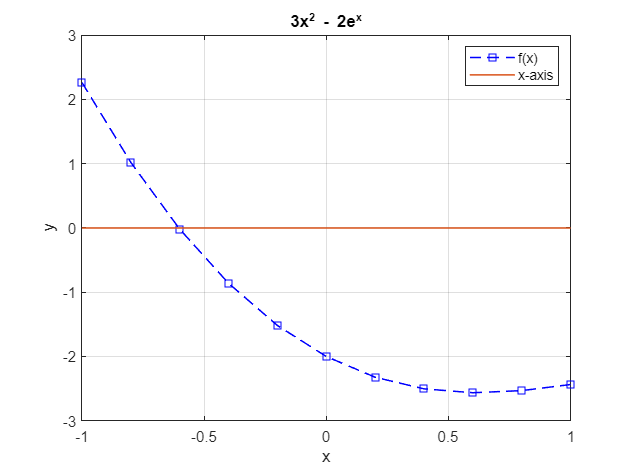

f = @(x) (3 * x.^2) - (2 * exp(x));
tol = 1 * 10^(-5);
g = @(x) 0 * x;
x = [-1:.2:1];

% Find y values 
y = f(x);
gy = g(x);
% Plot function 1 * 10^(-5)
plot(x,y,'--bs', x, gy,'LineWidth', 1);

% Label axes
title('3x^2 - 2e^x')
xlabel('x');
ylabel('y');
grid on;
legend('f(x)', 'x-axis');



bisection_method(f,-1,1,tol,18);

    0.5000

    0.2500

    0.1250

    0.0625

    0.0312

    0.0156

    0.0078

    0.0039

    0.0020

   9.7656e-04

   4.8828e-04

   2.4414e-04

   1.2207e-04

   6.1035e-05

   3.0518e-05

   1.5259e-05

   7.6294e-06

   -0.6037

    17

   7.6294e-06



secant_method(f,-1, 1,tol,10);

    1.0367

    3.8911

    3.7357

    0.1204

    0.3814

    0.1051

    0.0143

   6.8358e-04

   -0.6037

     8

   5.3160e-06



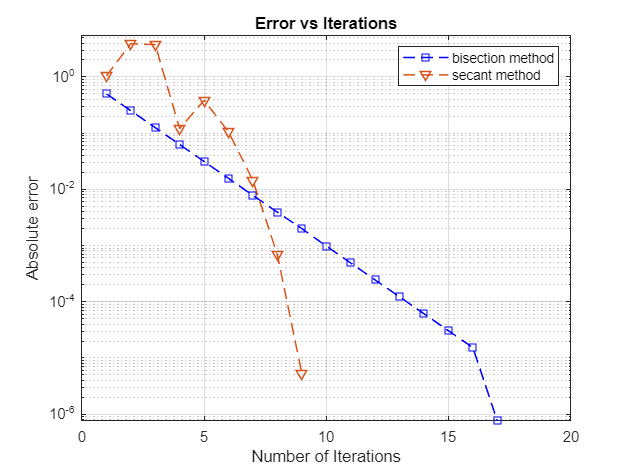

by = [0.5 0.25 0.125 0.0625 0.0312 0.0156 0.0078 0.0039 0.0020 0.00097656 0.00048828 0.00024414 0.00012207 0.000061035 0.000030518 0.000015259 0.00000076294];
bx = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17];
sy = [1.0367 3.8911 3.7357 0.1204 0.3814 0.1051 0.0143 0.00068358 0.0000053160 NaN NaN NaN NaN NaN NaN NaN NaN];
sx = [1 2 3 4 5 6 7 8];
semilogy(bx,by,'--bs',bx,sy, '--v', 'LineWidth', 1);
legend('bisection method','secant method');
title('Error vs Iterations')
xlabel('Number of Iterations');
ylabel('Absolute error');
grid on;

xlim([0.0000001 18])
ylim([0 4])

xlim([0.0 20])
ylim([0.00 5.52])